Consider a clamped-pinned beam modelled by von Karman beam theory.

clear all; clc

## Model Setup

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Getting nonlinearity coefficients
Assembling Tensors


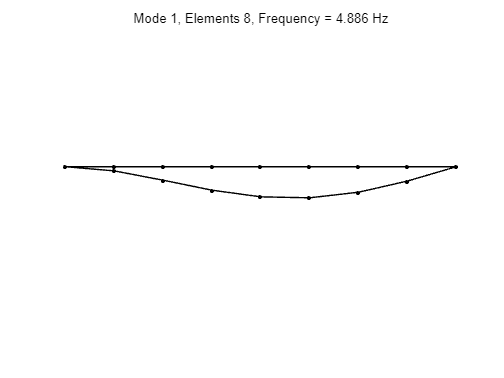

Assembling external force vector


nElements = 8;
kappa = 1e5; % strong damping
[M,C,K,fnl,~,outdof] = build_model(nElements,kappa);

n = length(M);

### Dynamical System Setup

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',11,'Nmax',10,'notation','multiindex','outDOF',outdof)

**Add external forcing and also control matrix**

Bext     = zeros(n,1); Bext(outdof(2),1)=1; 
ExtForce = @(t) Bext*sin(20*t+15*t/(2+sin(t)));
epsilon  = 50;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 11 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.411040e-02
modal damping ratio for 2 mode is 1.105810e-01
modal damping ratio for 3 mode is 2.310303e-01
modal damping ratio for 4 mode is 3.963511e-01
modal damping ratio for 5 mode is 6.084896e-01
modal damping ratio for 6 mode is 8.705050e-01
modal damping ratio for 7 mode is 1.182038e+00
modal damping ratio for 8 mode is 1.644161e+00
modal damping ratio for 9 mode is 2.089910e+00
modal damping ratio for 10 mode is 2.665776e+00
modal damping ratio for 11 mode is 3.373412e+00

 The first 22 nonzero eigenvalues are given as 
   1.0e+04 *
  -0.0001 + 0.0031i
  -0.0001 - 0.0031i
  -0.0011 + 0.0099i
  -0.0011 - 0.0099i
  -0.0048 + 0.0202i
  -0.0048 - 0.0202i
  -0.0141 + 0.0328i
  -0.0141 - 0.0328i
  -0.0333 + 0.0435i
  -0.0333 - 0.04

## SSM Reduced dynamics 

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 5;

**Reduced dynamics simulation**

*Construction of initial condition*

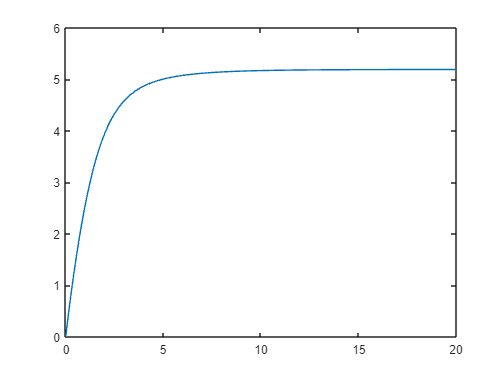

om = 2*pi/20;
nsteps = 500;
DSstatic = DynamicalSystem();
set(DSstatic,'M',M,'C',1000*C,'K',K,'fnl',fnl);
set(DSstatic.Options,'HarmonicForce',false);
fmidspan = zeros(n,1);
fmidspan(outdof(2)) = 1500;
Fmidspan = @(t) fmidspan;
set(DSstatic,'fext',Fmidspan);
[ts, xs, xf] = time_integration_transient(DSstatic,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',zeros(2*n,1));
figure;
plot(ts,xs(:,2))


% master subspace
% modes = [1 2 3 4];
modes = [1 2];
S.choose_E(modes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 19121
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2
These are in resonance with the follwing eigenvalues of the master subspace
  -1.0472 +30.6815i
  -1.0472 -30.6815i
sigma_in = 19121


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 4.93E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.69E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 8.54E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.10E-01 MB


% construct initial condition
z0 = xf';

auData = construct_autoData(DS, modes, R_0);
cont   = struct();
cont.Q    = blkdiag(0.1*eye(n),zeros(n));
cont.Rhat = 0.01;
cont.Mhat = 0.2*eye(2*n)*0;
cont.zd   = 0;

% first segment
t0 = 0; t1 = 0.2;
tspan = linspace(t0,t1,nsteps);
om = 2*pi/t1;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0,'ts',0);

## Cut-off Criteria

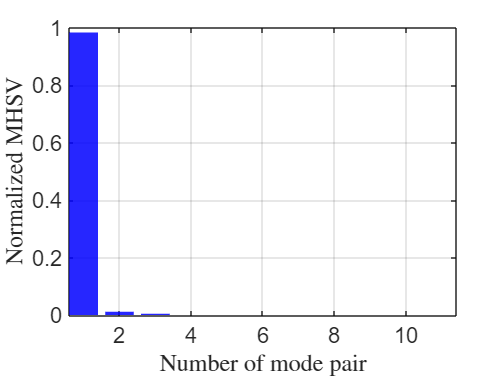

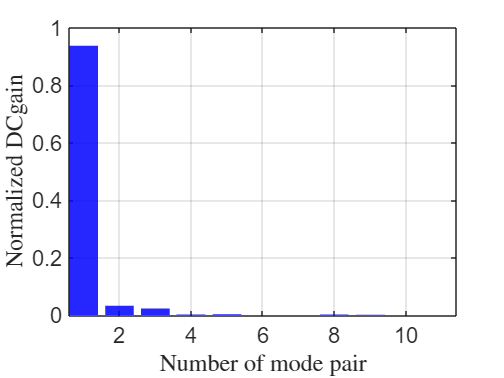

MHSV sum of the first 5 pair
    0.9837
DCgain sum of the first 5 pair
    0.9380


res = Cutof_LQR_closed_loop_MT2_comp(DS,11);

#### **1 Segment - closed loop**

traj_closed1 = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
Call fminunc to find the projection of point on SSM
approx error
   7.3095e+03
approx error
   7.3095e+03
approx error
   7.3095e+03
approx error
   3.0316e+04
approx error
   3.0316e+04
approx error
   3.0316e+04
approx error
   1.1953e+03
approx error
   1.1953e+03
approx error
   1.1953e+03
approx error
  391.2525
approx error
  391.2525
approx error
  391.2527
approx error
  171.0855
approx error
  171.0856
approx error
  171.0855
approx error
  161.1380
approx error
  161.1380
approx error
  161.1380
approx error
  137.7864
approx error
  137.7865
approx error
  137.7865
approx error
   86.1321
approx error
   86.1321
approx error
   86.1322
approx error
   39.3073
approx error
   39.3073
approx error
   39.3073
approx error
   36.4909
approx error
   36.4909
approx error
   36.4909
approx error
   32.7210
approx error
   32.7210
approx error
   32.7210
approx error
   28.6193
approx error
   28.6193
approx error
   28.6193
approx error
 

% full dynamic
om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.9978
Iteration 1, Residual norm = 4.7322e-06
Iteration 2, Residual norm = 1.8059e-14
time integration completed: 0.2%
Iteration 0, Residual norm = 0.97534
Iteration 1, Residual norm = 1.2003e-05
Iteration 2, Residual norm = 9.6942e-14
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99038
Iteration 1, Residual norm = 3.5766e-06
Iteration 2, Residual norm = 3.9182e-14
time integration completed: 0.6%
Iteration 0, Residual norm = 0.89223
Iteration 1, Residual norm = 5.8748e-06
Iteration 2, Residual norm = 5.0705e-14
time integration completed: 0.8%
Iteration 0, Residual norm = 0.97903
Iteration 1, Residual norm = 2.8799e-06
Iteration 2, Residual norm = 3.0175e-14
time integration completed: 1%
Iteration 0, Residual norm = 0.79176
Iteration 1, Residual norm = 3.159e-06
Iteration 2, Residual norm = 9.768e-14
time integration completed: 1.2%
Iteration 0, Residual norm = 0.96742
Iteration 1, Residual norm = 2.4e-06
Iteration 2, Residual norm = 3.

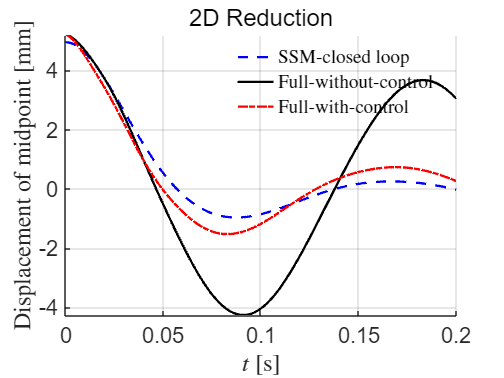


figure; hold on
plot(traj_closed1.time, traj_closed1.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);

plot(tfullwo, xfullwo(:,2),'k-','DisplayName','Full-without-control','LineWidth',2);
plot(tfullwc, xfullwc(:,2),'r-.','DisplayName','Full-with-control','LineWidth',2);
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('Displacement of midpoint [mm]','Interpreter','latex');
title([num2str(numel(modes)),'D Reduction'])

set(gca,'FontSize',18);
grid on, axis tight
legend('show','Interpreter','latex'); legend boxoff
set(gca,'FontSize',18); grid on, axis tight

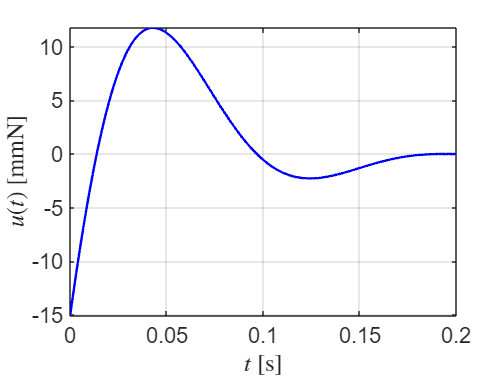



figure;
plot(traj_closed1.time,traj_closed1.ut(1,:),'b-','LineWidth',2); hold on
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [mmN]','Interpreter','latex')

set(gca,'FontSize',18); grid on, axis tight

#### 2 Segments** - closed loop**


t0 = 0; t1 = 0.1;
tspan3 = linspace(t0,t1,nsteps);
traj3 = LQR_closed_loop(DS,z0,'nonlinear',tspan3,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
Call fminunc to find the projection of point on SSM
approx error
   7.3095e+03
approx error
   7.3095e+03
approx error
   7.3095e+03
approx error
   3.0316e+04
approx error
   3.0316e+04
approx error
   3.0316e+04
approx error
   1.1953e+03
approx error
   1.1953e+03
approx error
   1.1953e+03
approx error
  391.2525
approx error
  391.2525
approx error
  391.2527
approx error
  171.0855
approx error
  171.0856
approx error
  171.0855
approx error
  161.1380
approx error
  161.1380
approx error
  161.1380
approx error
  137.7864
approx error
  137.7865
approx error
  137.7865
approx error
   86.1321
approx error
   86.1321
approx error
   86.1322
approx error
   39.3073
approx error
   39.3073
approx error
   39.3073
approx error
   36.4909
approx error
   36.4909
approx error
   36.4909
approx error
   32.7210
approx error
   32.7210
approx error
   32.7210
approx error
   28.6193
approx error
   28.6193
approx error
   28.6193
approx error
 

ufun3 = @(t) transpose(interp1(traj3.time,traj3.ut',t,'linear','extrap'));
set(DS,'u',ufun3);
[tfull3, xfull3,x3f,xt3] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0);

t2 = 0.2;
tspan4 = linspace(t1,t2,nsteps);
traj4  = LQR_closed_loop(DS,x3f','nonlinear',tspan4,auData,W_0,modes,1:2,cont);

pl
   0.4026 + 0.2186i
   0.4026 - 0.2186i
Call fminunc to find the projection of point on SSM
approx error
  214.6360
approx error
  214.6360
approx error
  214.6360
approx error
   6.0988e+04
approx error
   6.0988e+04
approx error
   6.0988e+04
approx error
  804.0432
approx error
  804.0432
approx error
  804.0430
approx error
  214.1969
approx error
  214.1969
approx error
  214.1969
approx error
  212.7020
approx error
  212.7019
approx error
  212.7020
approx error
  212.6526
approx error
  212.6526
approx error
  212.6526
approx error
  212.2562
approx error
  212.2562
approx error
  212.2562
approx error
  210.0300
approx error
  210.0300
approx error
  210.0300
approx error
  208.7248
approx error
  208.7248
approx error
  208.7248
approx error
  207.8242
approx error
  207.8242
approx error
  207.8242
approx error
  207.7568
approx error
  207.7568
approx error
  207.7568
approx error
  207.7563
approx error
  207.7563
approx error
  207.7563
approx error
  207.7563
approx e

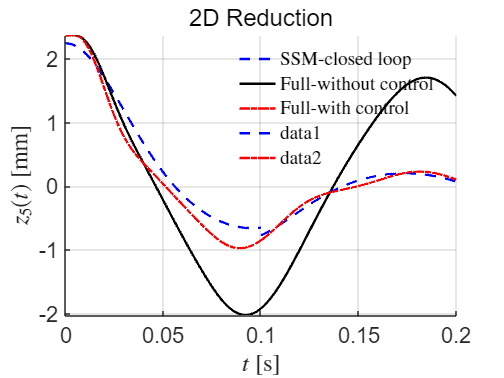


ufun4 = @(t) transpose(interp1(traj4.time,traj4.ut',t,'linear','extrap'));
set(DS,'u',ufun4);
[tfull4, xfull4,x4f,xt4] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',x3f','ts',t1);
% outdof 5
figure; hold on
plot(traj3.time, traj3.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
% plot(traj3.time, traj3.zt_auto(1,:),'b-','DisplayName','W(p)');
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfull3, xfull3(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);
plot(traj4.time, traj4.zt(1,:),'b--','LineWidth',2);
% plot(traj4.time, traj4.zt_auto(1,:),'b-');
plot(tfull4, xfull4(:,1),'r-.','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$z_{',num2str(outdof(1)),'}(t)$ [mm]');
ylabel(zk,'Interpreter','latex');
title([num2str(numel(modes)),'D Reduction'])
set(gca,'FontSize',18);
grid on, axis tight

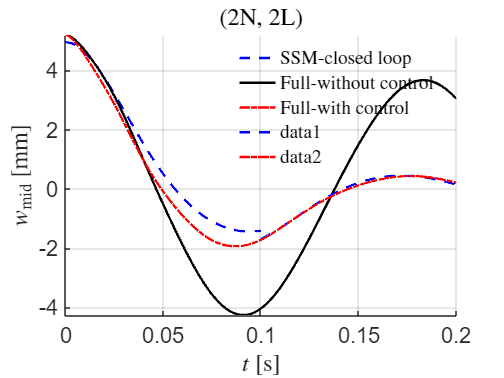


% outdof 11
figure; hold on
plot(traj3.time, traj3.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
% plot(traj3.time, traj3.zt_auto(1,:),'b-','DisplayName','W(p)');
plot(tfullwo, xfullwo(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfull3, xfull3(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);
plot(traj4.time, traj4.zt(2,:),'b--','LineWidth',2);
% plot(traj4.time, traj4.zt_auto(1,:),'b-');
plot(tfull4, xfull4(:,2),'r-.','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(2)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
ylabel('$w_\mathrm{mid}$ [mm]','Interpreter','latex');
title('(2N, 2L)', 'Interpreter','latex')
set(gca,'FontSize',18);
grid on, axis tight

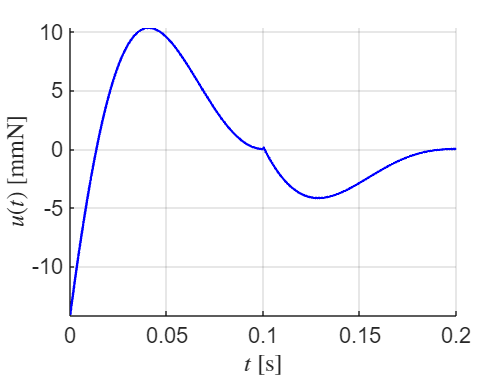


figure;
hold on
plot(traj3.time,traj3.ut(1,:),'b-','LineWidth',2); 
plot(traj4.time,traj4.ut(1,:),'b-','LineWidth',2);

xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [mmN]','Interpreter','latex')

set(gca,'FontSize',18); grid on, axis tight

## Vibration video

% 
% % vt  =  [xt3; xt4];
% % n   = size(vt,1);
% % 
% % hfig = figure;
% % hold on;
% % for i = 1:n
% %     clf;
% %     Draw(nElements,kappa,vt(i,:));
% %     saveas(gcf, ['frame' num2str(i, '%03d') '.png']);
% %     drawnow
% %     close(gcf)
% % end
% 
% % Hermite interpolation
% tt     = [tfull3; tfull4];
% output     = [xt3; xt4];
% n      = length(tt);
% li0    = linspace(0,2.7,9); 
% delta_l = output(:,[1,4,7,10,13,16,19]);
% xt      = [zeros(n,1),delta_l,zeros(n,1)] + li0;
% xt      = xt .* 1000; % m to mm
% zt      = [zeros(n,1),output(:,[2,5,8,11,14,17,20]),zeros(n,1)];
% theta_t = [zeros(n,1), output(:,[3,6,9,12,15,18,21,22])];
% z_prime = tan(theta_t);
% % x_val   = linspace(0,2700,100);
% interp_num = 50;
% total_num  = interp_num * nElements;
% hFig = figure('Position', [0, 0, 800, 400]);
% hold on;
% xticks(0:300:2700)
% yticks(-2:1.0:6)
% xlim([0,2700])
% ylim([-2,6])
% xlabel("x/mm")
% ylabel("z/mm")
% box on;  % 显示所有坐标轴
% % hFig.DataAspectRatioMode = 'manual';  % 设置比例模式为手动
% % hFig.DataAspectRatio = [1 1.1 factor];  % 设置x轴、y轴和z轴的比例
% for i = 1:n
%     x_val      = zeros(total_num,1);
%     z_val      = zeros(total_num,1);
%     for k = 1:nElements 
%         [A,b] = Ab_form(xt(i,k:k+1),zt(i,k:k+1),z_prime(i,k:k+1));
%         a_4   =  Gram_Schmidt(A,b');
%         x_val((k-1)*interp_num+1 : k*interp_num) = linspace(xt(i,k), xt(i,k+1),interp_num);
%         z_val((k-1)*interp_num+1 : k*interp_num) = HerFunc(a_4, x_val((k-1)*interp_num+1 : k*interp_num));
%     end
%     % z_interpolated = interp1(xt(i,:), [zt(i,:), z_prime(i,:)], x_val, 'spline', 'extrap');
%     beamDisplacement = plot(x_val, z_val, 'b-');
%     beamsca = scatter(xt(i,:), zt(i,:), 'ko');
%     drawnow
%     frame = getframe(gcf);
%     imwrite(frame.cdata, ['frame' num2str(i, '%03d') '.png']);
%     delete(beamDisplacement);
%     delete(beamsca)
% end
% close(hFig)
% % % 初始化 figure
% % hFig = figure;
% % 
% % % 添加梁的基线
% % beamBaseline = plot(0, 'k-');
% % hold on;
% % xlim([0,2700])
% % ylim([-2,5.2])
% % % 动画循环
% % for i = 1:n
% %     % 绘制当前时间点的位移
% %     beamDisplacement = plot(xt(i,:), zt(i,:), 'bo-');
% % 
% %     % 更新标题，显示当前时间
% %     % title(['Time = ', num2str(tt(i))]);
% % 
% %     % 可选：添加坐标轴标签等
% %     xlabel('x/mm');
% %     ylabel('z/mm');
% % 
% %     % 暂停一段时间以控制动画速度
% %     % pause(0.0001);
% %     drawnow
% %     % 保存每一帧，如果需要创建 GIF
% %     % frame = getframe(gcf);
% %     frame = getframe(gcf);
% %     imwrite(frame.cdata, ['frame' num2str(i, '%03d') '.png']);
% %     % print(gcf, ['frame' num2str(i, '%03d') '.png'], '-dpng');
% %     % 清除之前的位移图形
% %     delete(beamDisplacement);
% % end
% % 
% % 
% % 
% % % 关闭 figure
% % % close(hFig);
% % 
% % pngFiles = dir('*.png');
% % % Read all PNG images
% % numImages = numel(pngFiles);
% % frames = cell(1, numImages);
% % 
% % for i = 1:numImages
% %     frames{i} = imread(pngFiles(i).name);
% %     % frames{i} = imresize(frames{i}, [656, 875]);
% % end
% % 
% % % Create a video
% % outputVideo = VideoWriter('output.avi');
% % open(outputVideo);
% % 
% % for i = 1:numImages
% %     writeVideo(outputVideo, frames{i});
% % end
% % 
% % close(outputVideo);


